# MHKiT CDIP IO

MHKiT includes functions to pull data directly from the Coastal Data Information Program ([CDIP](http://cdip.ucsd.edu/m/about/)), an extensive network for monitoring waves and beaches along the coastlines of the United States.

## Quick Start

The `cdip_request_parse_workflow` function is your one-stop shop for pulling and parsing data. If a station number is passed the function will pull the buoy data from the CDIP servers and then proceed to process the data for the user. `cdip_request_parse_workflow` allows the user to slice data between a start and/or end date. Alternatively, the user may specify a single year or multiple years of interest. To reduce processing time `cdip_request_parse_workflow` will allow the user to specify parameters of interest and only return data for the specified parameters. By default, the `cdip_request_parse_workflow` will pull historic data, but the user may also specify real-time data if interested. Lastly, due to the long processing time, two-dimensional (2D) data is not returned by default. If **all** 2D data is desired the boolean `all_2D_variables` may be specified as *true*. It is recommended, however, that if 2D data is needed that the user passes that parameter in the parameters field. For a full list of 1D, 2D, and metadata variables see the CDIP reference [here](https://docs.google.com/document/d/1Uz_xIAVD2M6WeqQQ_x7ycoM3iKENO38S4Bmn6SasHtY/edit) (see BUOY VARIABLES).

## 1. Request Data from CDIP

In the above example, `cdip_request_parse_workflow` is used to both request and parse the CDIP data using multiple MHKiT functions in a prespecfied workflow for the user.

MHKiT can be used to request historical or realtime data from the CDIP buoys. A station table and map can be found [here](http://cdip.ucsd.edu/m/stn_table/) to determine a buoy of interest. To get started we will call historic data from station number 100. The function will return a structure with all historic 1D data and metadata. The 'data' and 'metadata' each hold different types of data based based on a prefix used on the variable returned by CDIP. Example prefixes are 'wave', 'sst', and 'gps', which are described in further detail below.

station_number = '100'; % TORREY PINES OUTER, CA - 100: http://cdip.ucsd.edu/m/products/?stn=100p1
data_type = 'historic';
buoy_data = cdip_request_parse_workflow( ...
    'station_number', station_number, ...
    'data_type', data_type);
disp("Returned data:  " + string(strjoin(fieldnames(buoy_data))))

Returned data:  data metadata


## 2. View the Returned Data

### 2.a The 'data' field

As can be seen above the function has returned a structure with two field names:

`    1. 'data' - field with subfields referring to the data type. Possible subfields include:`

`        a. 'wave' - includes processed variables such as Hs, and Tp`

`        b. 'sst' - timeseries of sea surface tempature`

`        c. 'gps' - timeseries of buoy latitude and longitude`

`        d. 'dwr' - directional waverider contains information about accelerometer and buoy batery level`

`        e. 'wave2D' - arrays which are of height time and have columns of wave frequency.`

`    2. 'metadata' - any other data not of length time or a 2D variable. This has the same fields as the 'data' field above.`

`        a. 'meta' - processed variables which started with the meta prefix and are not part of the variable prefixes listed below`

`        b. 'wave' - includes processed variables such as Hs, and Tp`

`        c. 'sst' - timeseries of sea surface tempature`

`        d. 'gps' - timeseries of buoy latitude and longitude`

`        e. 'dwr' - directional waverider contains information about accelerometer and buoy battery level`

`        f. 'wave2D' - arrays which are of height time and have columns of wave frequency.`

By selecting the subfield `data.wave` we can see the associated array for the wave data. The array is summarized below where one can see the values of each metric. By selecting the subfield `data.waveTime` we can see the associated timestamps.

buoy_data.data.wave

ans = struct with fields:
               waveDp: [379560×1 double]
      waveFlagPrimary: [379560×1 double]
    waveFlagSecondary: [379560×1 double]
               waveHs: [379560×1 double]
          wavePeakPSD: [379560×1 double]
      waveSourceIndex: [379560×1 double]
               waveTa: [379560×1 double]
             waveTime: [379560×1 datetime]
               waveTp: [379560×1 double]
               waveTz: [379560×1 double]


### 2.b The 'metadata' field

The metadata field stores anything not of length time for each of the previous fields. This field also has the 'meta' key for any data returned that started with the meta prefix.

fieldnames(buoy_data.metadata)

ans = 5×1 cell array
    {'meta'   }
    {'other2D'}
    {'wave'   }
    {'wave2D' }
    {'name'   }


buoy_data.metadata.meta

ans = struct with fields:
         metaDeclination: [18×1 single]
      metaDeployLatitude: [18×1 single]
     metaDeployLongitude: [18×1 single]
         metaGridMapping: [64×1 char]
     metaInstrumentation: [64×1 char]
            metaPlatform: [64×1 char]
     metaStationLatitude: 32.9314
    metaStationLongitude: -117.3918
         metaStationName: [64×1 char]
          metaWaterDepth: [18×1 single]


## 3. Plotting

The wave graphics package has two CDIP stylized plots, [boxplot](http://cdip.ucsd.edu/themes/media/docs/documents/html_pages/annualHs_plot.html) and [compendium](http://cdip.ucsd.edu/themes/media/docs/documents/html_pages/compendium.html).  The CDIP scripts these are based on are hyperlinked.

### 3.a The Box Plot

The CDIP stylized box plot is designed to group a passed parameter by months and display descriptive statistics. Below the plot is a general box plot legend showing the outliers as red plus signs, and the 25-percentile and 75-percentile mark the edges of the box. The median is shown as a red line in the box and the mean is shown as a green line with the mean annotated in green above the line. The x-axis has the month name at the bottom and the number of data points in each month at the top.

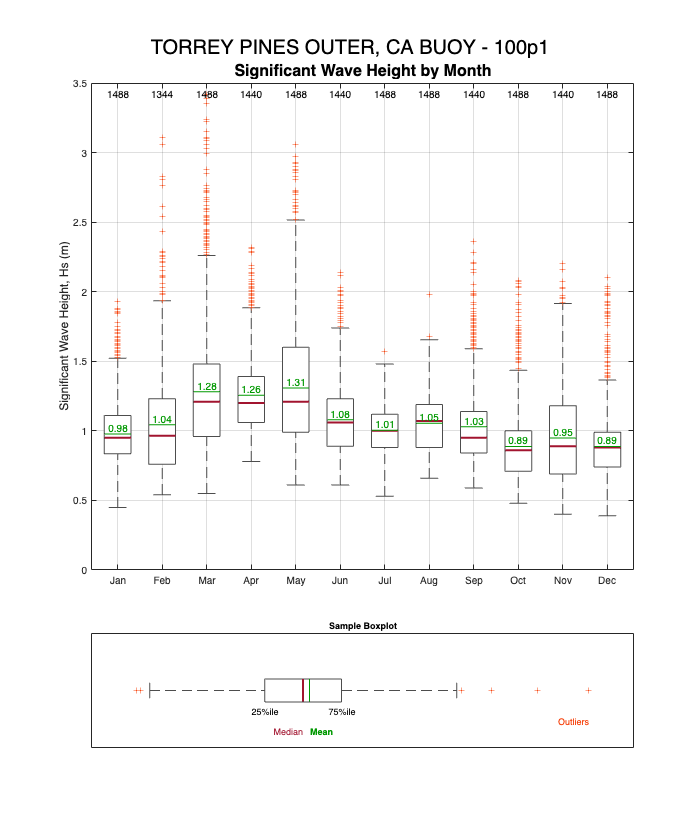

buoy_data_2011 = cdip_request_parse_workflow( ...
    'station_number', station_number, ...
    'years', 2011, ...
    'data_type', data_type);
Hs_2011_data = buoy_data_2011.data.wave.waveHs;
time_2011 = buoy_data_2011.data.wave.waveTime;
buoy_name = buoy_data_2011.metadata.name;
plot_boxplot(Hs_2011_data, time_2011, 'buoy_title', buoy_name);

### 3.b CDIP Compendium Plot

The compendium plot is a time series summary plot of three variables (Hs, Tp, and Dp). To return the plot simply pass these variable from the `data.wave` structure.

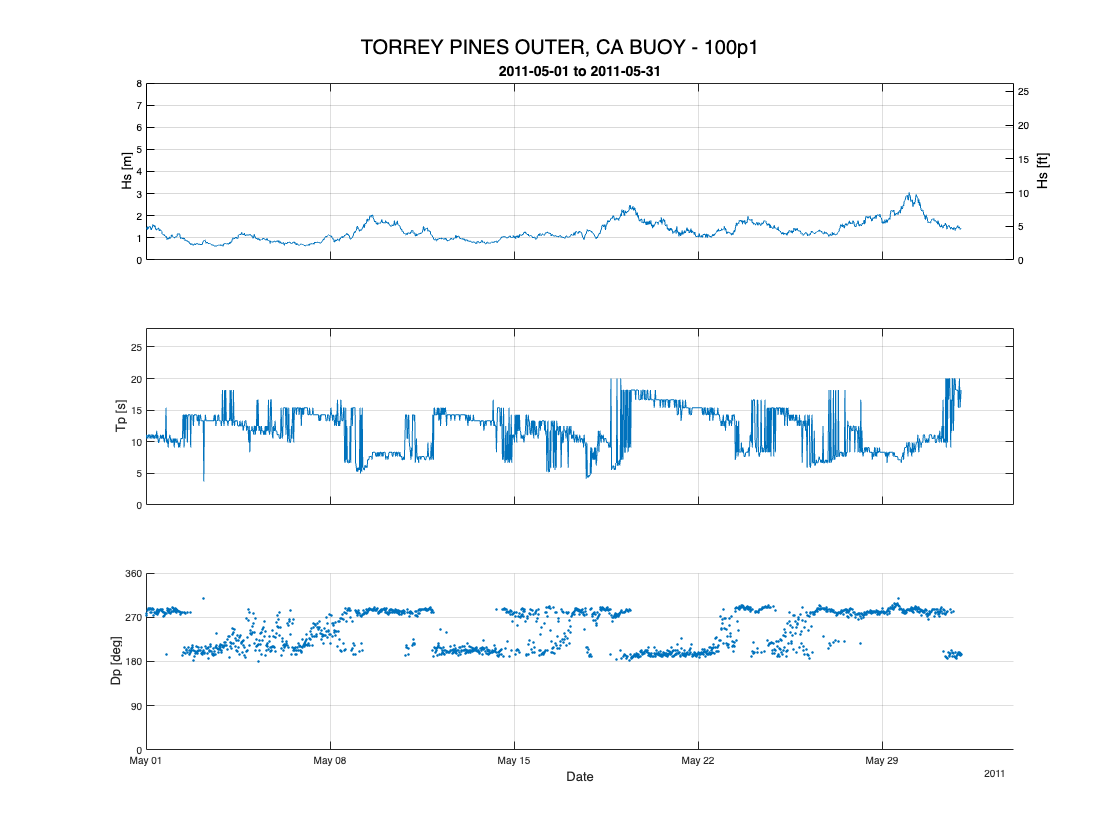

wave_data_May_2011 = cdip_request_parse_workflow( ...
    'station_number', station_number, ...
    'start_date', '2011-05-01', ...
    'end_date', '2011-05-31', ...
    'data_type', data_type);
Hs = wave_data_May_2011.data.wave.waveHs;
Tp = wave_data_May_2011.data.wave.waveTp;
Dp = wave_data_May_2011.data.wave.waveDp;
time = wave_data_May_2011.data.wave.waveTime;
plot_compendium(Hs, Tp, Dp, time, "buoy_title", buoy_name);

## 4. Advanced Queries

In this section we will show more on how to slice on time ranges of interest.

### 4.a  *start_date*, *end_date* and *parameters*

The function `cdip_request_parse_workflow` can iterate over and extract variables from CDIP buoy netCDF data. It takes inputs of `start_date`, `end_date`, `parameters`, and `all_2D_variables`. The start and end date parameters allow us to specify string dates of interest in which to include data after the start date and before the end date. These are specified as a string with precision down to the day in 'YYYY-MM-DD' format. Specifying particular parameters of interest allows for faster processing times and data handling. For a complete list of parameters see Buoy Variables [here](https://docs.google.com/document/d/1Uz_xIAVD2M6WeqQQ_x7ycoM3iKENO38S4Bmn6SasHtY/edit). Lastly, we can specify to return all 2D variables, although this is not recommended unless a user truly plans to use all the data because of the significant processing time.

For an example we will create a box plot of Hs for the year 2011.

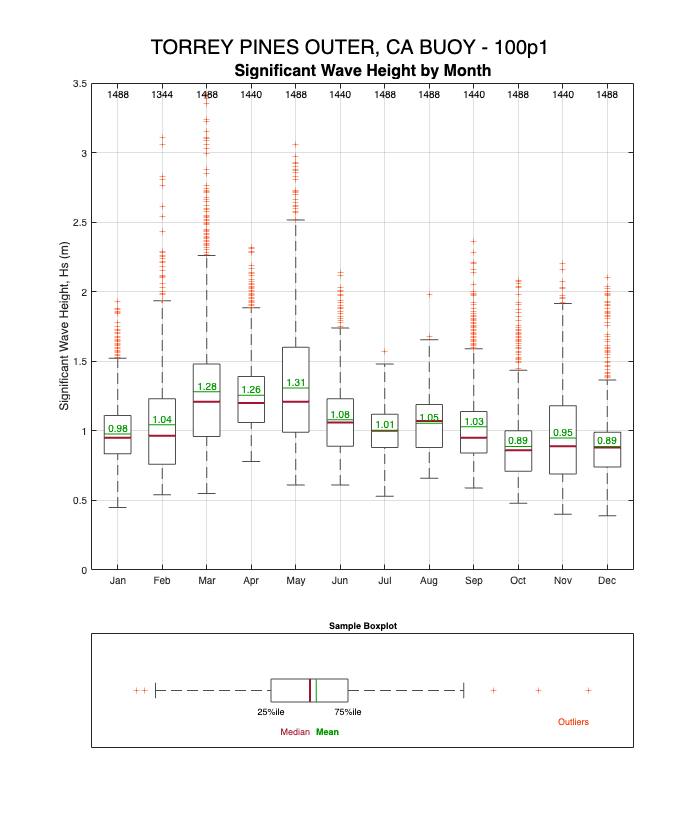

buoy_data = cdip_request_parse_workflow( ...
    'station_number', station_number, ...
    'start_date', '2011-01-01', ...
    'end_date', '2011-12-31', ...
    'parameters', {'waveHs'}, ...
    'data_type', data_type);
buoy_name = buoy_data.metadata.name;
plot_boxplot( ...
    buoy_data.data.wave.waveHs, ...
    buoy_data.data.wave.waveTime, ...
    "buoy_title", buoy_name);

### 4.b  *years* and 2D data

The function `cdip_request_parse_workflow` is especially useful for processing 2D data, which is only processed when specifically requested due to the amount of time it takes. Next, `cdip_request_parse_workflow` will slice on time by years, start_date, or end date. Years can be a single integer or an array of integers and is not required to be consecutive. If specified, the start date will remove any data prior to the specified string (e.g. '2011-01-01') and end_date will remove any data after the speficied date. start_date and end_date may be used together, separately or not at all. Years works independently of start and end date. Next, the data_type defaults to historic but specifying this as realtime will return realtime data from the buoy. Lastly, there is the boolean `all_2D_variables`. If set to true, the function will return all of the wave 2D variables. It is not recommended to do this due to the computational expense, instead it is recommended to specify 2D quantities of interest using the `parameters` parameter.

For an example we will create a compendium of Hs, Tp and Dp for the year 2011. In this case we can use the years parameter instead of start and end dates.

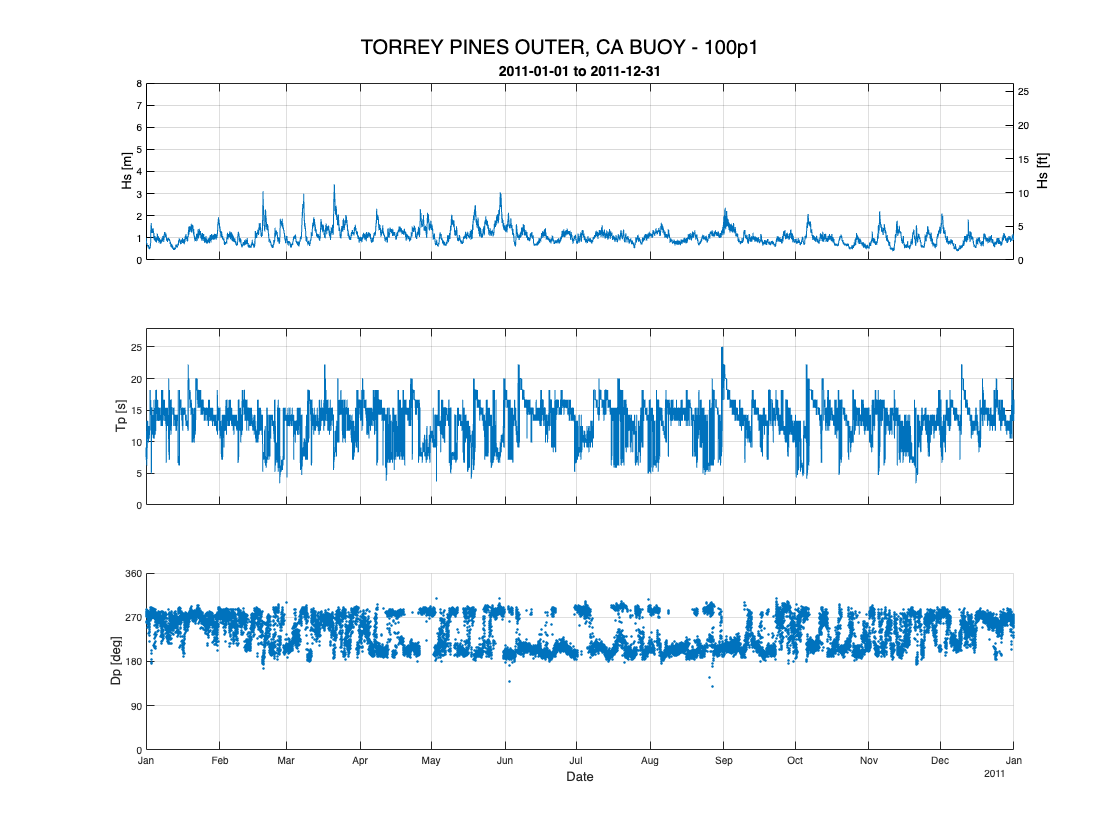

buoy_data = cdip_request_parse_workflow( ...
    'station_number', station_number, ...
    'years', 2011, ...
    'parameters', {'waveHs', 'waveTp', 'waveDp'});
Hs = buoy_data.data.wave.waveHs;
Tp = buoy_data.data.wave.waveTp;
Dp = buoy_data.data.wave.waveDp;
time = buoy_data.data.wave.waveTime;
buoy_name = buoy_data.metadata.name;
plot_compendium(Hs, Tp, Dp, time, "buoy_title", buoy_name);